Monte Carlo for Seat Arrangement

parpool;

tic
n = 100;
m = 1e6;
P = ones(m,n);
for s = 3:n
parfor k = 1:m
seat = randperm(s,2)
P(k,s) = abs(seat(1)-seat(2))==1||abs(seat(1)-seat(2))==s-1;
end
end
p = sum(P)/m;
toc

历时 17.864494 秒。


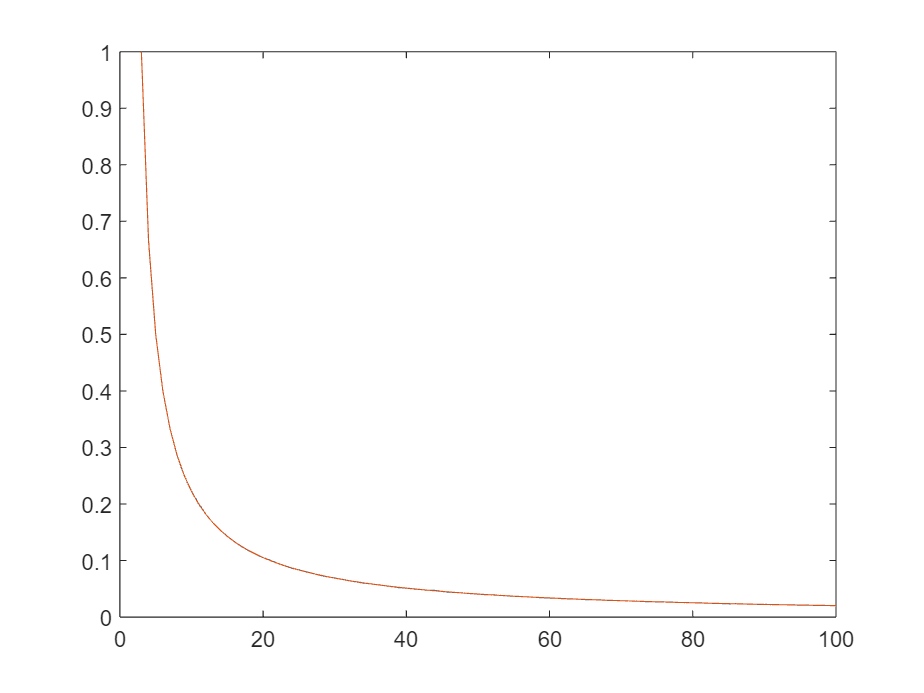

clf
theoryp = [1,1,(2./((3:n)-1))];
plot(3:n,p(3:n))
hold on
plot(3:n,theoryp(3:n))

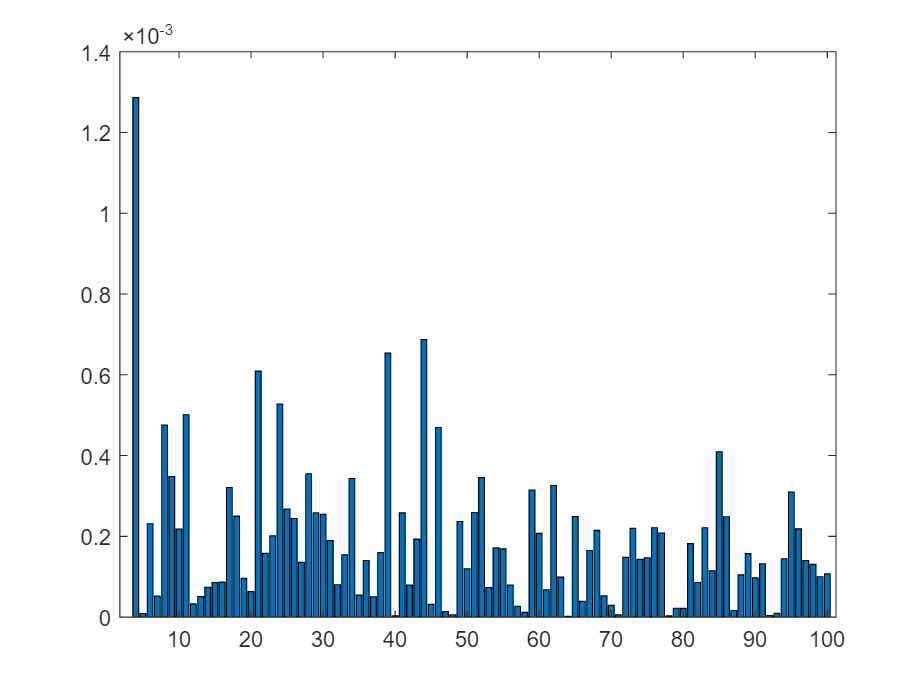

clf
bar(3:n,abs(p(3:n)-(2./((3:n)-1))))

The theoretical solution should be $P(n) = \frac{n \cdot A^2_2 \cdot A^{n-2}_{n-2}}{A^n_n}=\frac{2}{n-1}$ when n>2

(2) The following figure shows how the mean of errors for n=3:100 declines as the experiment times increases.

What we do here is we test every n 1e6 times, and we record the outcome of every single experiment. To get the error of given experiment time m, we calculate the number of success upto k with function cumsum, then we divide the sum by m, now we have obtain an approximation for the probability.

Taking the loglog on both side, we can see the plot is linear.

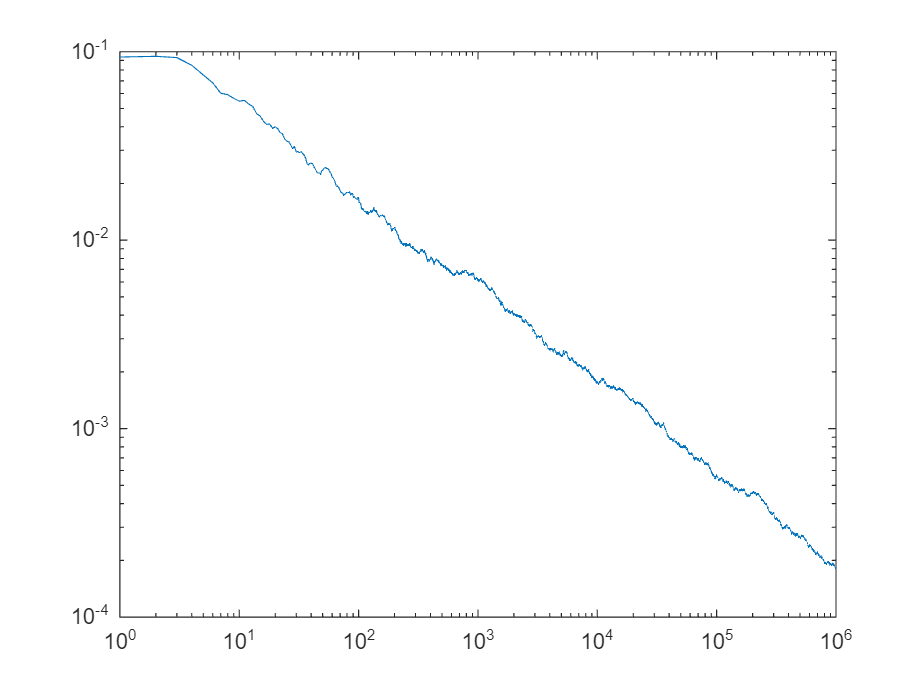

clf
loglog(mean(abs(cumsum(P,1)./repmat((1:m)',1,n)-repmat(theoryp,m,1)),2))

polyfit(log(1:1e6),log(mean(abs(cumsum(P,1)./repmat((1:m)',1,n)-repmat(theoryp,m,1)),2)),1)

ans =    -0.5255   -1.4728


Apply polyfit to aforementioned line, we know its slope is around -3/2, that is:


$$log(Experiment)=-\frac{3}{2}log(Err)$$



$$\to Err=m^{-\frac{2}{3}}$$


2. Optimization for purchasing

Different from the on class case, here the best solution can be any real value. To get the best result, we will run genetic algorithm with simulated annealling here. We set the initial best value to 320 and start the random experiment and start our simulated annealing.

In each iteration, the vector x is chosed at random with randn, is this way, we get a series of x that is slightly different from our current best. Then we Search the best among our xs and see if the result is improved.

The mutation rate, here devoted by 2^-k, shrink as iterations procede.

tic
best = 300;
for k = 1:30
    n = randn(2e6,1)*28+320;
    x = [randn(100,1)*28*(1.5^-k);0]+best;
    [X,N] = meshgrid(x,n);
    income = mean(min(X,N).*(3.5-2.2)+(N<X).*(N-X)*(3.5-1.2),1);%Calculate average income in each experiments
    %plot(x,income)
    best = x(income == max(income))
end

best = 310.2439

best = 310.2439

best = 310.0053

best = 310.0053

best = 310.0053

best = 310.0555

best = 310.0067

best = 310.0387

best = 310.0778

best = 310.0332

best = 310.0347

best = 310.0900

best = 310.0409

best = 310.0204

best = 310.0230

best = 310.0941

best = 310.0843

best = 310.0469

best = 310.0798

best = 310.0545

best = 310.0614

best = 310.0531

best = 310.0625

best = 310.0574

best = 310.0599

best = 310.0572

best = 310.0560

best = 310.0550

best = 310.0555

best = 310.0551

toc

历时 30.243439 秒。


best

best = 310.0551

We can know see the farmer can maximize his income if he buy 310.05 Chinese kilo of cabages.